# PID Controllers

## Feedback controller block diagram

Feedback controllers are pivotal in engineering and technology, serving as the backbone of countless systems that require precision, stability, and efficiency. At their core, these controllers monitor the output of a system and adjust the input based on a desired setpoint, effectively minimizing errors by comparing the actual output to the expected performance. This process of constant adjustment and regulation enables systems to maintain desired operation levels despite external disturbances or internal changes. From simple household appliances to complex industrial machinery, feedback controllers ensure that systems operate optimally, making them indispensable in achieving high levels of accuracy and reliability in automated processes.

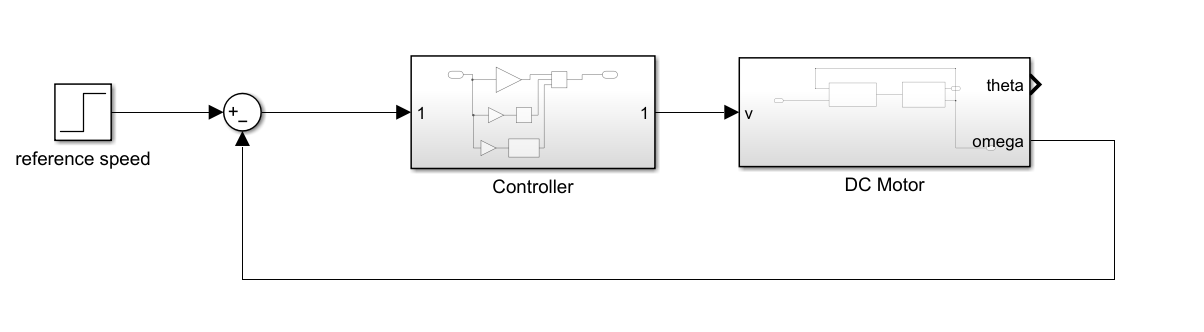

## Constructing the plant model

The equations governing the functioning of a DC motor are given as 


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$
 


$$
$ i' = \frac{1}{L} \left(v - Ri - k\omega \right)$$$


for the electical part, and 


$$J \dot{\omega} + B\omega  = k_m i$$
 


$$$ \omega' = \frac{1}{J}\left( Ki - B\omega \right) $$$


for the mechanical part. 

We will construct a Simulink plant model for a DC motor using the following parameter values 

***B***** = 0.028 **N$\cdot$m/(rad/s), **K = 0.05 **V/(rad/s),** L = 0.1 **H, **R = 0.25, **and **J = 3.37e-5**

## Compare Simulink and MATLAB simulations

- Comparing the step response of a system modeled in Simulink with that generated by MATLAB's step function, offers insight into the system's dynamics from two different simulation environments. 

- Simulink provides a visual approach, allowing for a detailed and intuitive construction of the system's block diagram,

- On the other hand, MATLAB's step function, when applied to a system object created by the tf function, offers a more analytical perspective, enabling quick calculations and plots of the system's step response based on the defined transfer function parameters. 

B = 0.028;
K = 0.05;
L = 0.1;
R = 0.25; 
J =  3.37e-5;
H = tf(K/(J*L),[1, (J*R+B*L)/(J*L), (B*R+K^2)/(J*L)])
b = (J*R+B*L)/(J*L);
c = (B*R+K^2)/(J*L); 
zeta = 0.5*(b/sqrt(c))
step(H)

## Adding disturbance to the plant model

- We will intentionally introduce a disturbance into our Simulink plant model. 

- This is to simulate real-world conditions where systems rarely operate in ideal environments. Disturbances can come in many forms, such as environmental changes, load variations, or equipment inconsistencies, and they significantly impact system performance. 

- Understanding how disturbances affect system behavior is crucial for developing robust control strategies that can maintain desired performance levels despite unpredictable changes. 

Add a distrubance to the plant model using a step block. Add this signal to the torque generated by the current. 

## Constructing the PID controller 

- We will delve into the architecture of PID controllers by sequentially integrating the Proportional (P), Integral (I), and Derivative (D) components and observing their individual and collective impacts on the system's performance. 

- Starting with the Proportional control, we will first witness how it adjusts the control signal in direct proportion to the error, setting the stage for understanding basic control actions. 

- Following this, the Integral component will be introduced, enhancing the system's ability to eliminate steady-state errors by accumulating past error values.

- Finally, the Derivative component will be added, providing a predictive element that reacts to the rate of change of the error, thus offering a means to anticipate system behavior. 

## Proportional control 

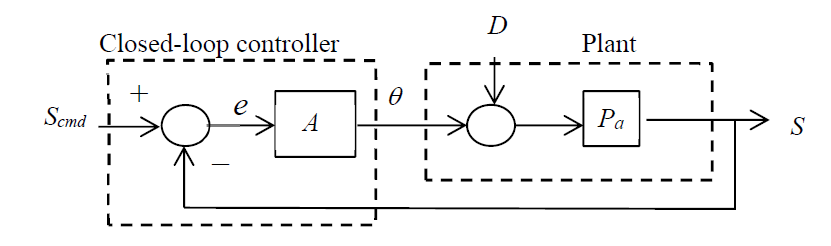

syms Scmd e A theta D Pa S
eqn = S == Pa*(A*(Scmd-S) + D); 

Sout = solve(eqn, S)

$$Sout = \frac{\mathrm{Pa}\,\left(\text{D}+A\,\mathrm{Scmd}\right)}{A\,\mathrm{Pa}+1}$$

Note that in the numerator, $S_{cmd}$ is multiplied by $A$but not $D$. This means the proportoinal controller magnifies the impact of only the input command and not the disturbance. 

Note that when $A \rightarrow \infty$, $S_{out}$ becomes independent of $D$.

## Filtered derivative

In PID (Proportional-Integral-Derivative) control, the derivative part is indeed ideally represented by just $s$ in the Laplace domain, which corresponds to differentiation in the time domain. However, we will use $\frac{100s}{s+100}$, which is a practical approach known as a "derivative filter" or "filtered derivative".

This modification is made for a few key reasons:

**1.** **Noise Reduction:** Pure differentiation $s$ is highly sensitive to noise, especially high-frequency noise. In real-world applications, measurement signals often contain a significant amount of noise. Applying a pure derivative would amplify this noise, potentially leading to instability or erratic control behavior.

The filter $\frac{100s}{s+100}$ acts to reduce the impact of high-frequency noise on the derivative calculation.

**Exercise:  **Compute and plot the frequency response (Bode plot) of the above transfer function 

%Enter your code here 



**2. Implementability:** A pure derivative $s$ is not physically realizable because it would require infinite gain at infinite frequency, which is not possible with real-world devices. The filtered derivative, however, has a bandwidth limit (in this case, defined by the 100 rad/s cutoff frequency), making it implementable with real electronic components.